HYY_st.name='HYY'; 
HYY_st.lat=61.84738441;
HYY_st.lon=24.2947798;
HYY_st.alt=181;
HYY_st.env='con';
HYY_st.footp='F';


HYY_rd=read_betsy('hyy_2006_2017_new',HYY_st.name);

HYY_rdO=read_betsy('hyy_2006_2017',HYY_st.name);

a=RHdataSMEARII {:,1:6};
RH=timetable(datetime((a)));
RH.U_S=RHdataSMEARII{:,7};
RH=retime(RH,'daily',@nanmedian);
HYY_rd=synchronize(HYY_rd,RH);

datevec(HYY_rd.Time(1))

ans =         2006           1           1           0           0           0


datevec(HYY_rd.Time(end))

ans =         2018           1           1           0           0           0


prctile(HYY_rd.U0_S11,[5 50 95])

ans =          0    9.9000   18.9350


prctile(HYY_rd.U_S,[5 50 95])

ans =     4.0990   14.3625   47.5035


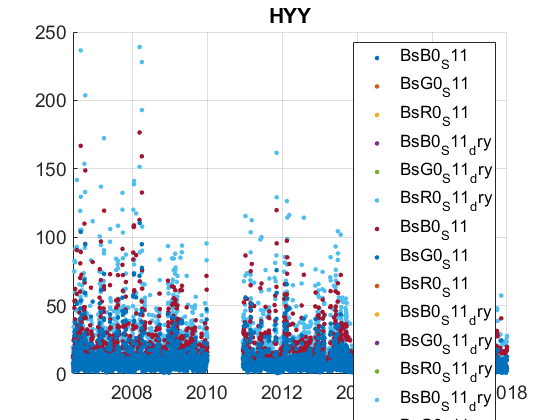

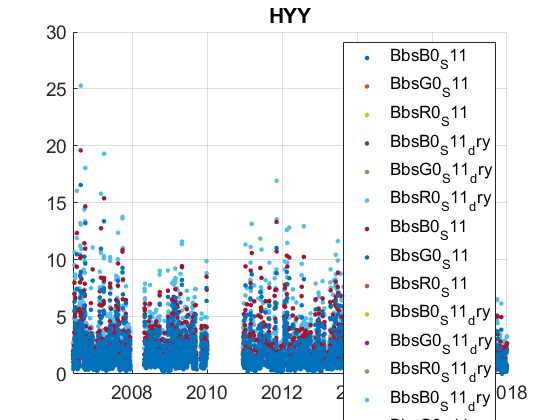

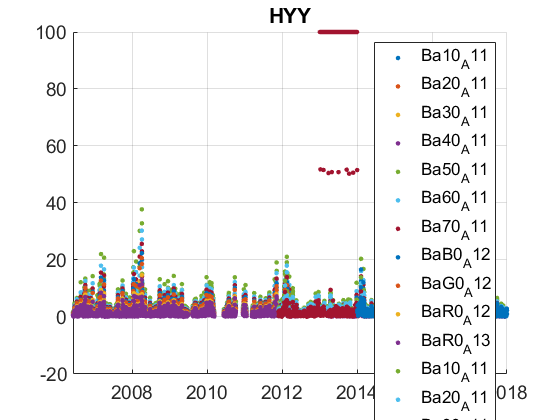

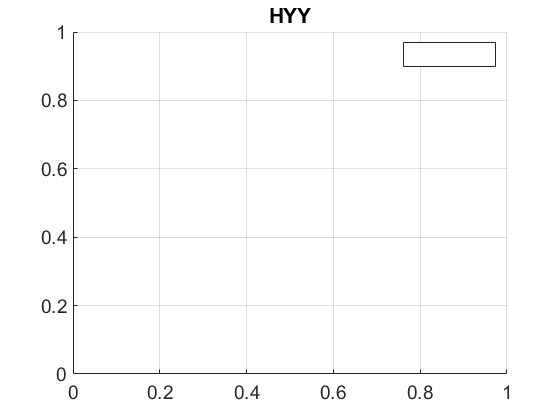

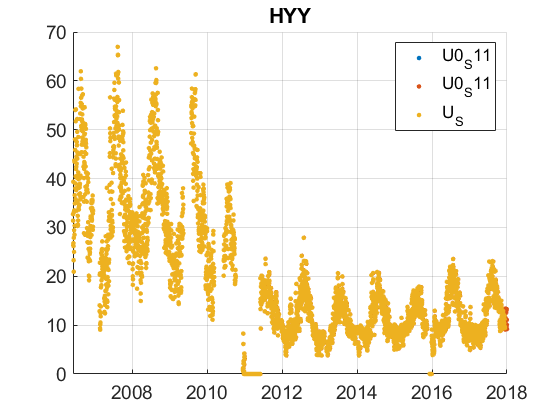

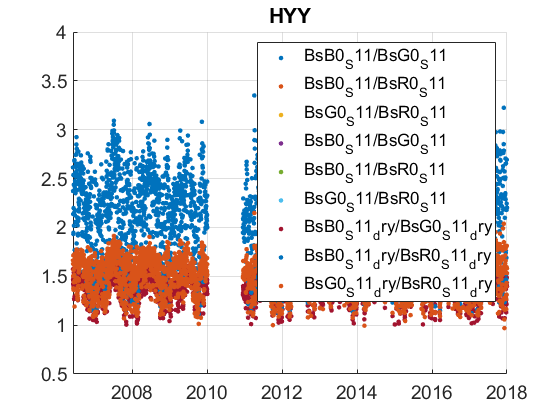

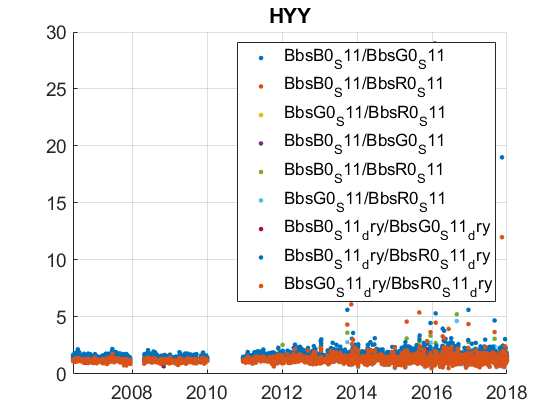

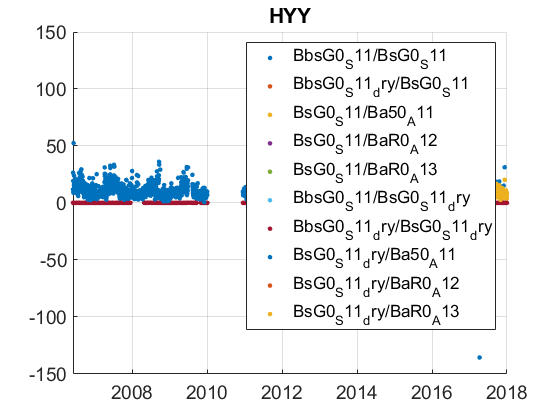

%  prctile(HYY_rd.U0_S,[5 50 95])
%  prctile(HYY_rd.U1_S,[5 50 95])
% prctile(HYY_rd.Uu1_S,[5 50 95])
plotFigControl(HYY_rd,HYY_st.name);

%plotFigControl(HYY_rdO,HYY_st.name);
% 1 size cut, ok, PM1 exists for some years (neph. 2011-2017, abs 2012.2017)
% sc: ok, no negatives,? clear seasonal cycle

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
HYY_cal=compute_exp_SSA(HYY_rd,lambdaSC, lambdaAE);
plotFigControl_cal(HYY_cal, HYY_st.name);


%Questions:
%problems:

%RH: very low, but rupture in 2015: before 0%-25% (decreasing with time), after: 5%-23% regular

%neph: all ok

%AE31 has almost no data: not use
%AE31: flag of 950 nm is false (==10)
%PSAP_A12: 3w: 2013: flag of red false A12: 2012.2016 data
%MAAP_A13:1w 2014-2017 data

HYY_tr=HYY_rd;
HYY_tr.y=year(HYY_tr.Time);
% begin at the beginning of a year: scat 2007
%end: 2017
P=timerange('2007-01-01','2018-01-01');
HYY_tr=HYY_tr(P,:);
%RH high at the beginning, but compute RH trend + dry
%delete PSAP and MAAP

names=fieldnames(HYY_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U0";"BaB";"BaG";"BaR";"BaR0_A13"]) ;
N=names(c);
for i=1:length(N)
    HYY_tr.(N{i})=[];
end

%U_S==zero=NaN
HYY_tr.U_S(HYY_tr.U_S<2)=NaN;
%take 2010 from rd0 for scat but not backscat
p1=timerange('2010-01-01','2011-01-01');
HYY_tr.BsB0_S11(p1)=HYY_rdO.BsB0_S11(p1);
HYY_tr.BsG0_S11(p1)=HYY_rdO.BsG0_S11(p1);
HYY_tr.BsR0_S11(p1)=HYY_rdO.BsR0_S11(p1);
% HYY_tr.BbsB0_S11(p1)=HYY_rdO.BbsB0_S11(p1);
% HYY_tr.BbsG0_S11(p1)=HYY_rdO.BbsG0_S11(p1);
% HYY_tr.BbsR0_S11(p1)=HYY_rdO.BbsR0_S11(p1);

HYY_tr.BsB0_S11_dry(p1)=HYY_rdO.BsB0_S11_dry(p1);
HYY_tr.BsG0_S11_dry(p1)=HYY_rdO.BsG0_S11_dry(p1);
HYY_tr.BsR0_S11_dry(p1)=HYY_rdO.BsR0_S11_dry(p1);
% HYY_tr.BbsB0_S11_dry(p1)=HYY_rdO.BbsB0_S11_dry(p1);
% HYY_tr.BbsG0_S11_dry(p1)=HYY_rdO.BbsG0_S11_dry(p1);
% HYY_tr.BbsR0_S11_dry(p1)=HYY_rdO.BbsR0_S11_dry(p1);

%use AE31 Ba10_A11

%compute SSA with AE31 and green
HYY_cal2=compute_exp_SSA(HYY_tr,lambdaSC, lambdaAE);

SCexclus = 3

ans = 1

ans = 816

ans = 0

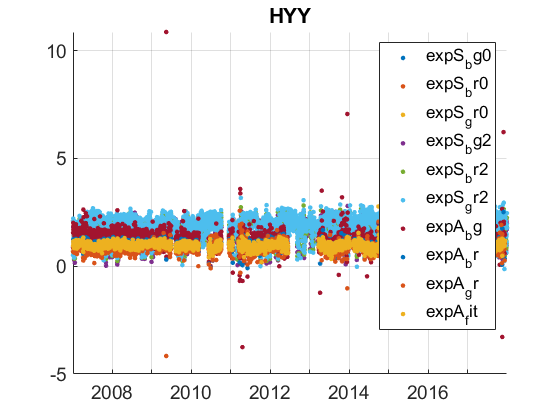

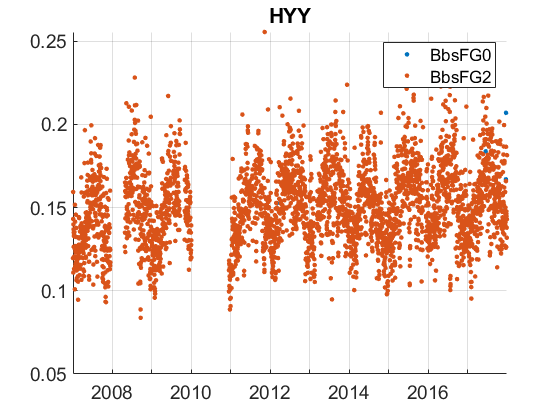

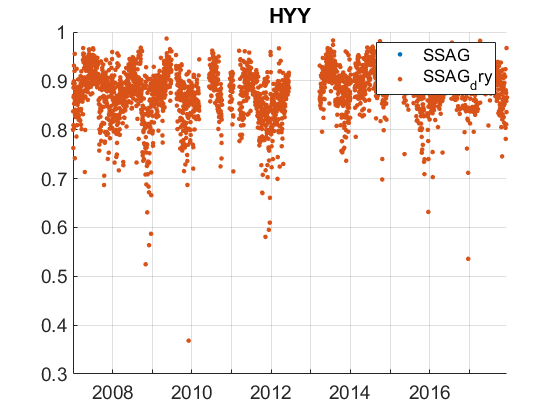

% absG is longer than absR --> compute SSA with green scat and abs
HYY_cal2.SSAG=HYY_tr.BsG0_S11./(HYY_tr.BsG0_S11+HYY_tr.Ba30_A11);
HYY_cal2.SSAG_dry=HYY_tr.BsG0_S11_dry./(HYY_tr.BsG0_S11_dry+HYY_tr.Ba30_A11);
plotFigControl_cal(HYY_cal2,HYY_st.name);

HYY_tr=outerjoin(HYY_tr, HYY_cal2);

% compute trend only on G

HYY_tr.BsB0_S11=[];
HYY_tr.BsR0_S11=[];
HYY_tr.BbsB0_S11=[];
HYY_tr.BbsR0_S11=[];
HYY_tr.BsB0_S11_dry=[];
HYY_tr.BsR0_S11_dry=[];
HYY_tr.BbsB0_S11_dry=[];
HYY_tr.BbsR0_S11_dry=[];

HYY_tr.Ba10_A11=[];
HYY_tr.Ba20_A11=[];
HYY_tr.Ba40_A11=[];
HYY_tr.Ba50_A11=[];
HYY_tr.Ba60_A11=[];
HYY_tr.Ba70_A11=[];
%ExpA: use fit:
HYY_tr.expA_bg=[];
HYY_tr.expA_br=[];
HYY_tr.expA_gr=[];

%use expS bg:
HYY_tr.expS_br0=[];
HYY_tr.expS_br2=[];
HYY_tr.expS_gr0=[];
HYY_tr.expS_gr2=[];



HYY_result= all_trend_STN(HYY_tr,HYY_st); 
plot_10y_in_two(HYY_result, HYY_st);

HYY_result_D=HYY_result;